# NSOLT Network Gallery

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2020a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2020-2021, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## Patch size

szPatchTrn = [32 32];

## Uniform decomposition for 2-D Grayscale image

% Decimation factor (Strides)
decFactor = [4 4]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [10 10]; % [Ps Pa] (Ps=Pa)

% Polyphase order
ppOrder = [2 2];

% No DC-leakage
noDcLeakage = true;

## Construction of layers

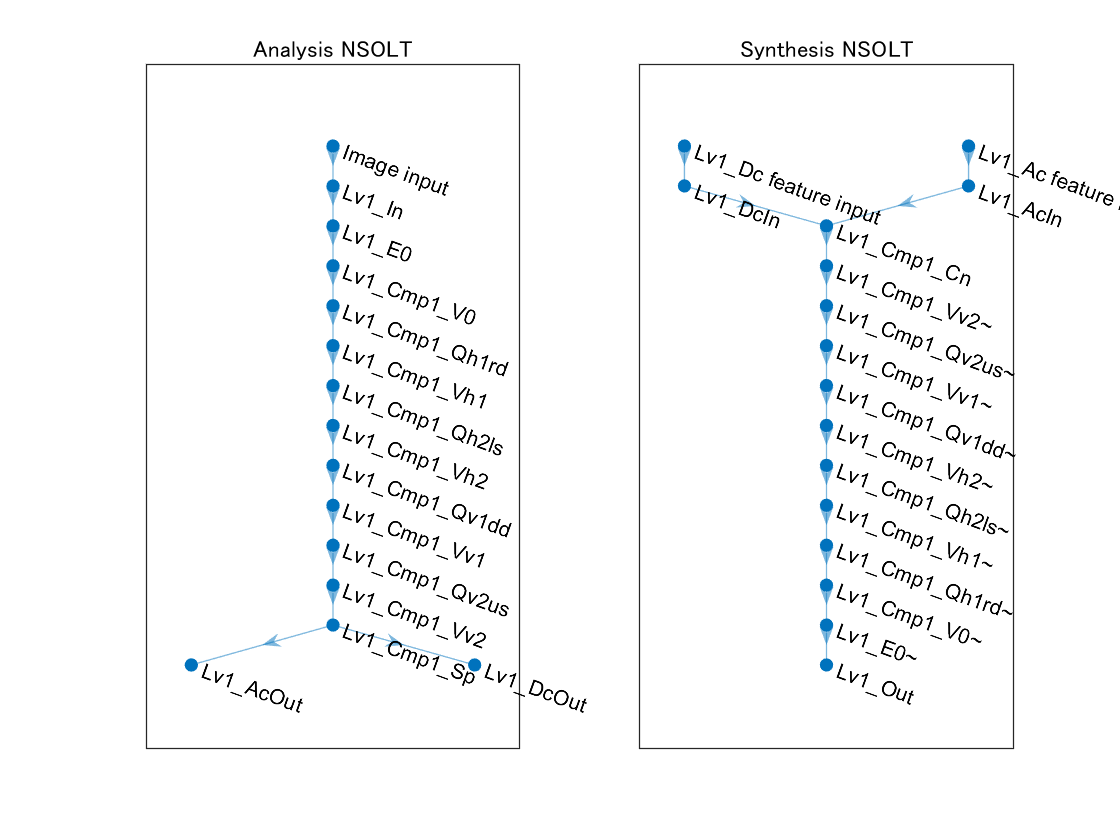

import saivdr.dcnn.*
analysislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Analyzer');
synthesislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Synthesizer');
figure(1)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

% Construction of synthesis deep learning network.
synthesisnet = dlnetwork(synthesislgraph);

% Initialize
stdInitAng = pi/6;
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
        synthesisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Construction of analyzer as the adjoint of synthesizer
synthesislgraph = layerGraph(synthesisnet);
analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2


analysisnet = dlnetwork(analysislgraph);



### Confirmation of the adjoint relation (perfect reconstruction)

x = rand(szPatchTrn,'single');
clear dls
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 1.5385e-11"



### Initial state of the atomic images

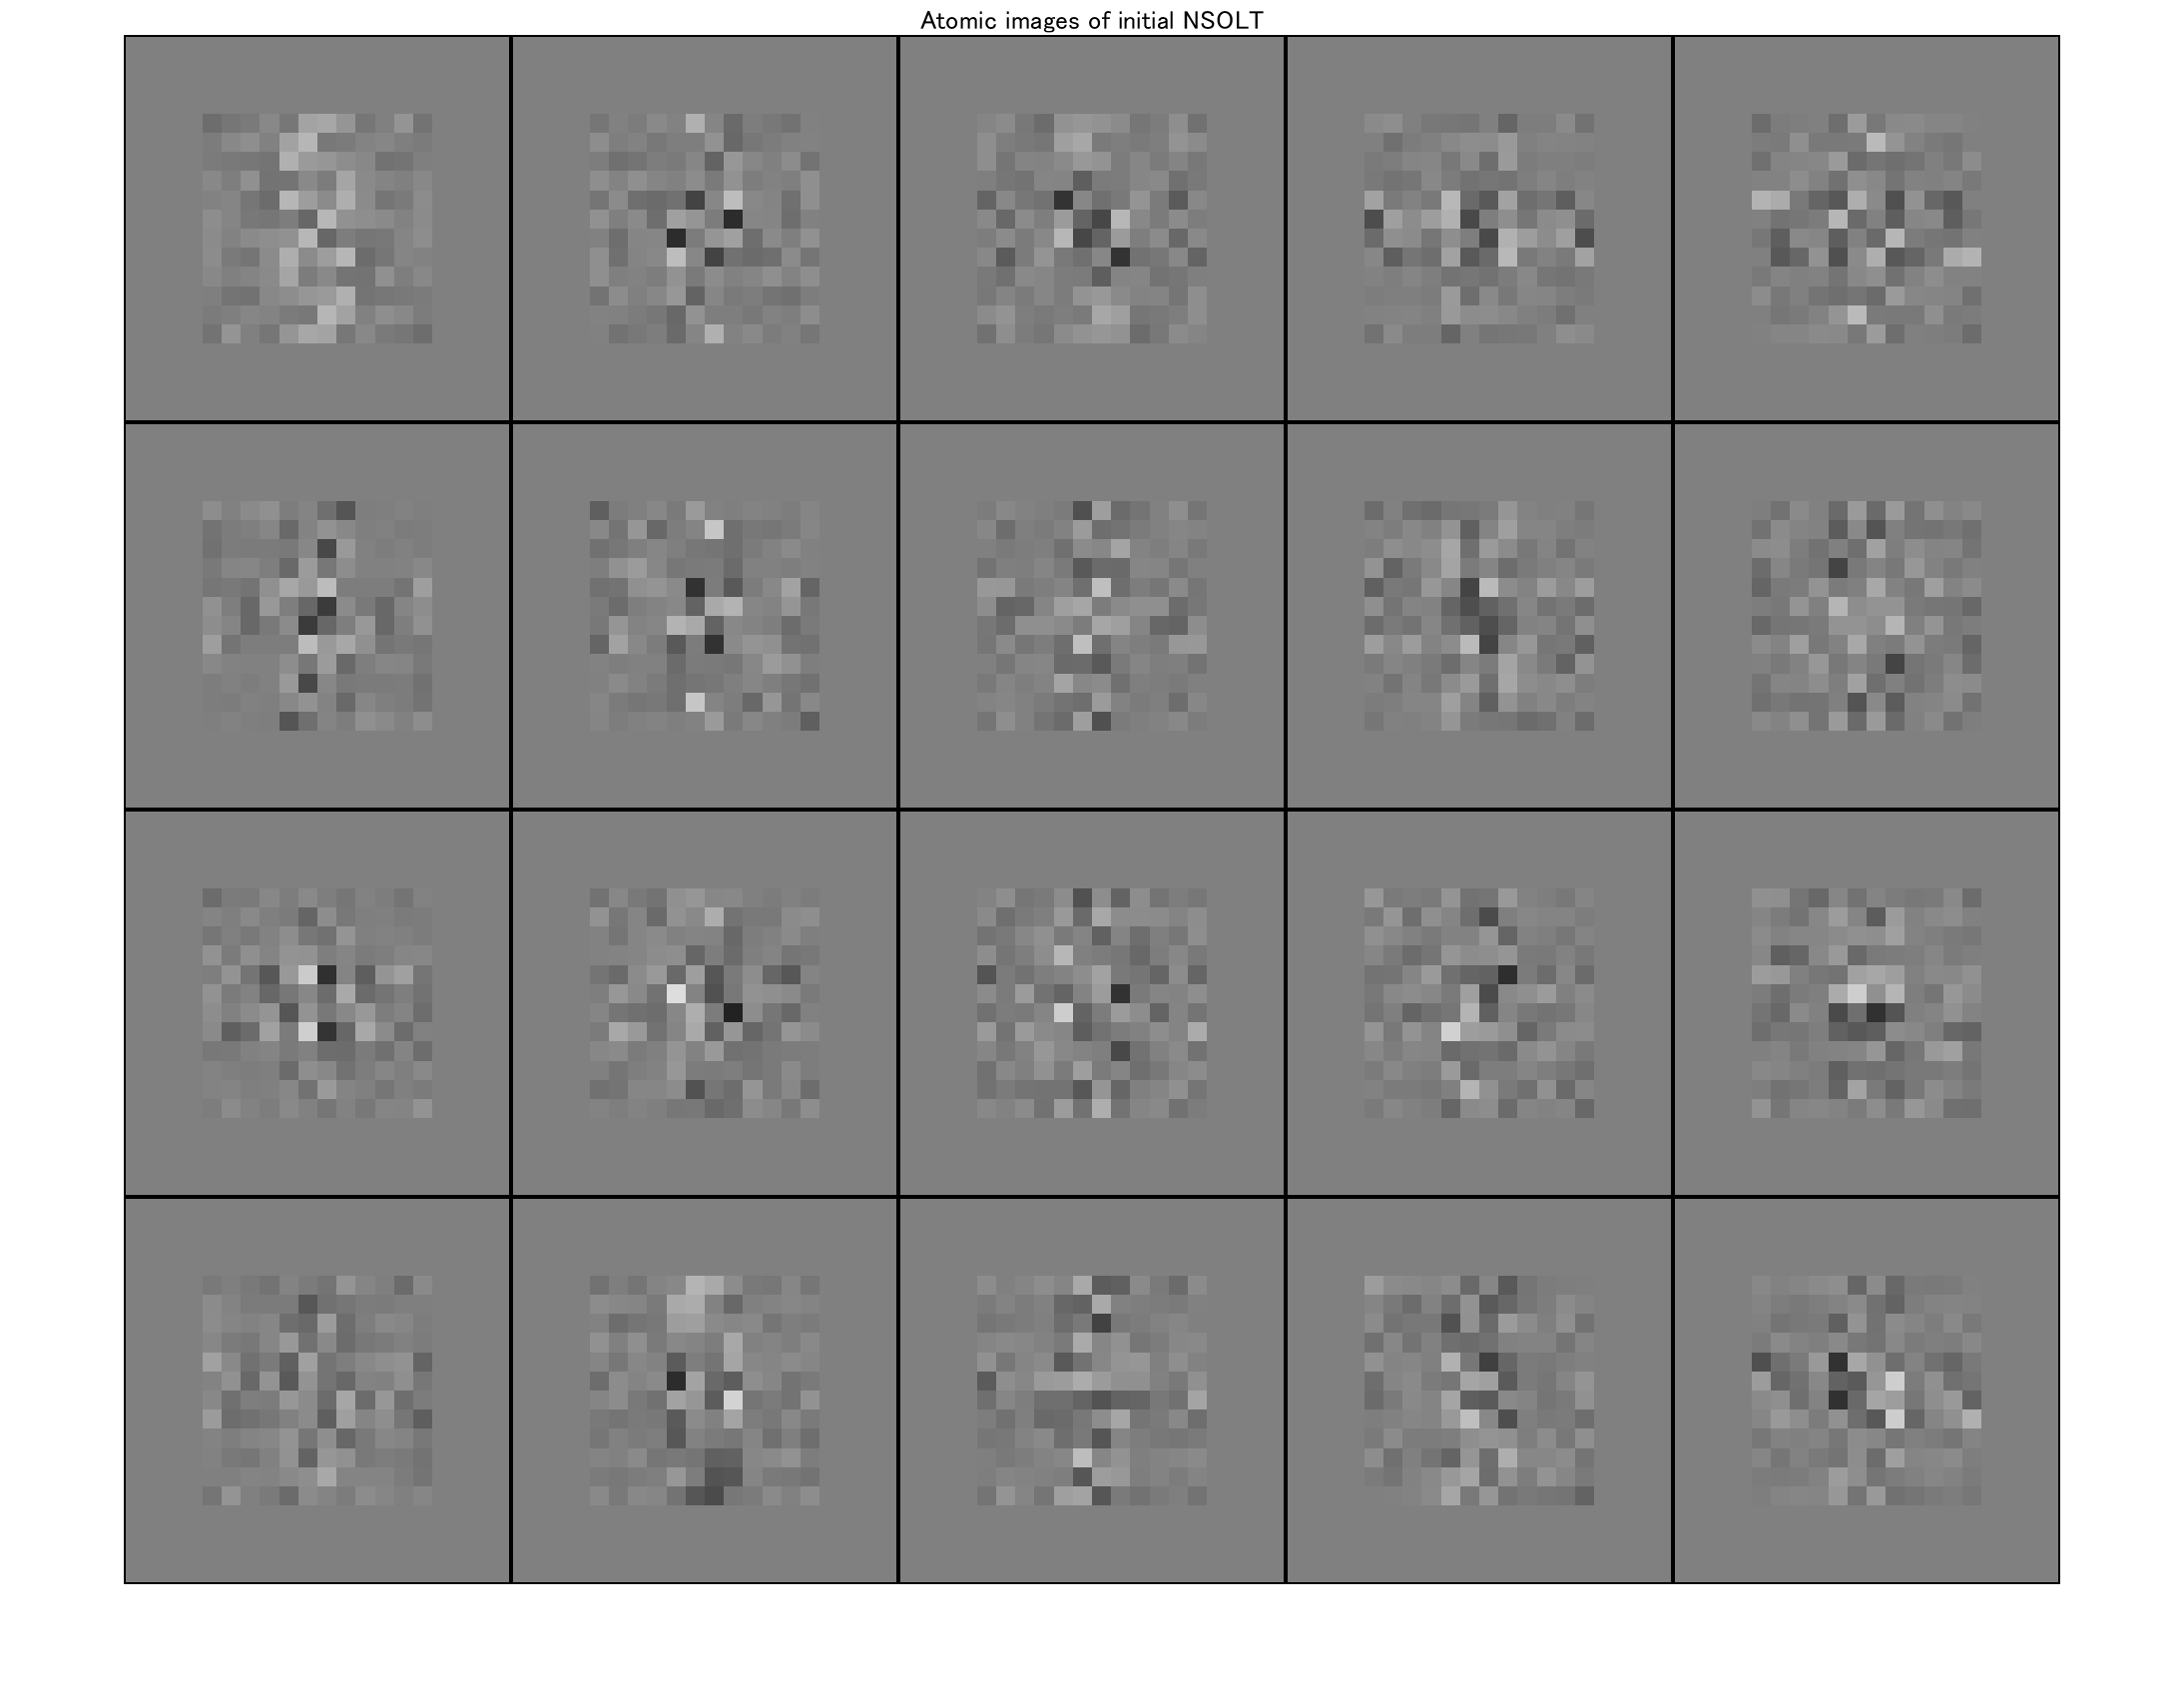

figure(2)
atomicimshow(synthesisnet)
title('Atomic images of initial NSOLT')

## Hierachical decomposition for 2-D Grayscale image

% Decimation factor (Strides)
decFactor = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 4% [Ps Pa] (Ps=Pa)

nChannels =      4     4



% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4



% Number of tree levels
nLevels = 3;

% No DC-leakage
noDcLeakage = true;

## Construction of layers

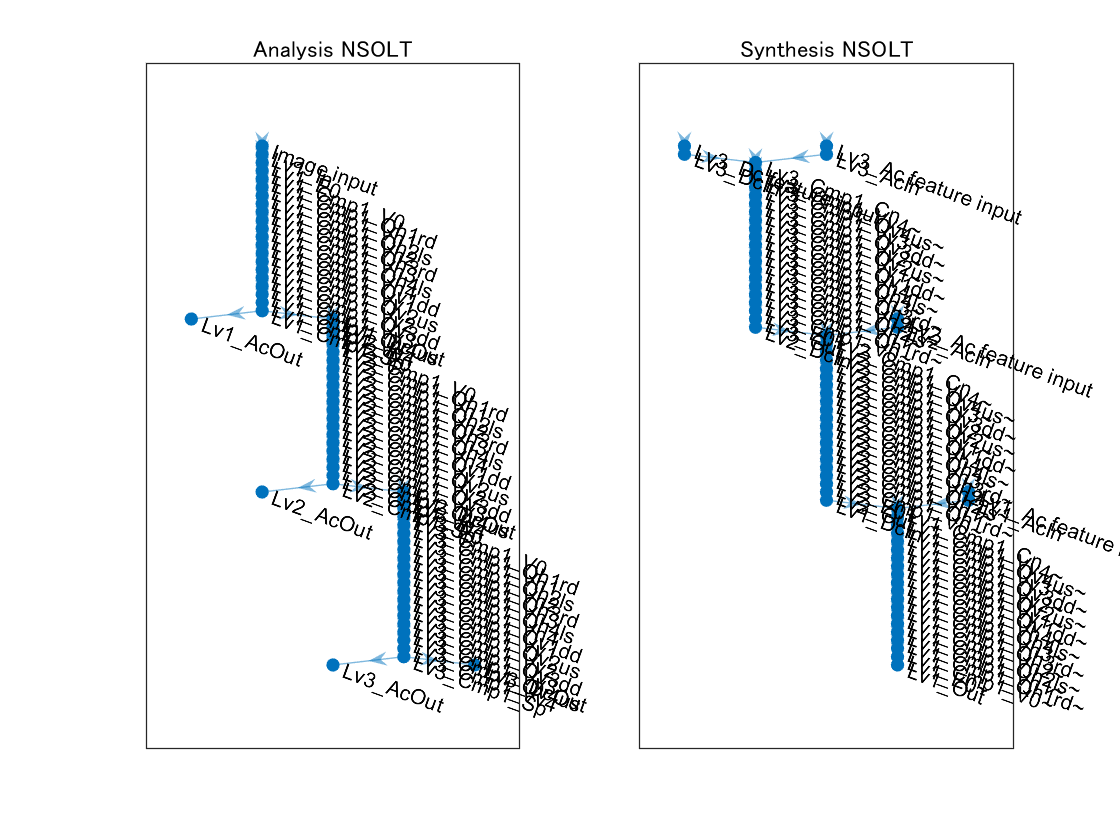

import saivdr.dcnn.*
analysislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Analyzer');
synthesislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NUmberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Synthesizer');

figure(3)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')


% Construction of synthesis deep learning network.
synthesisnet = dlnetwork(synthesislgraph);

% Initialize
stdInitAng = pi/6;
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
        synthesisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
synthesislgraph = layerGraph(synthesisnet);

% Construction of analysis deep learning network.
analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

analysisnet = dlnetwork(analysislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

x = rand(szPatchTrn,'single');
clear dls
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
[dls{1:nLevels+1}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 9.0108e-12"



### Initial state of the atomic images

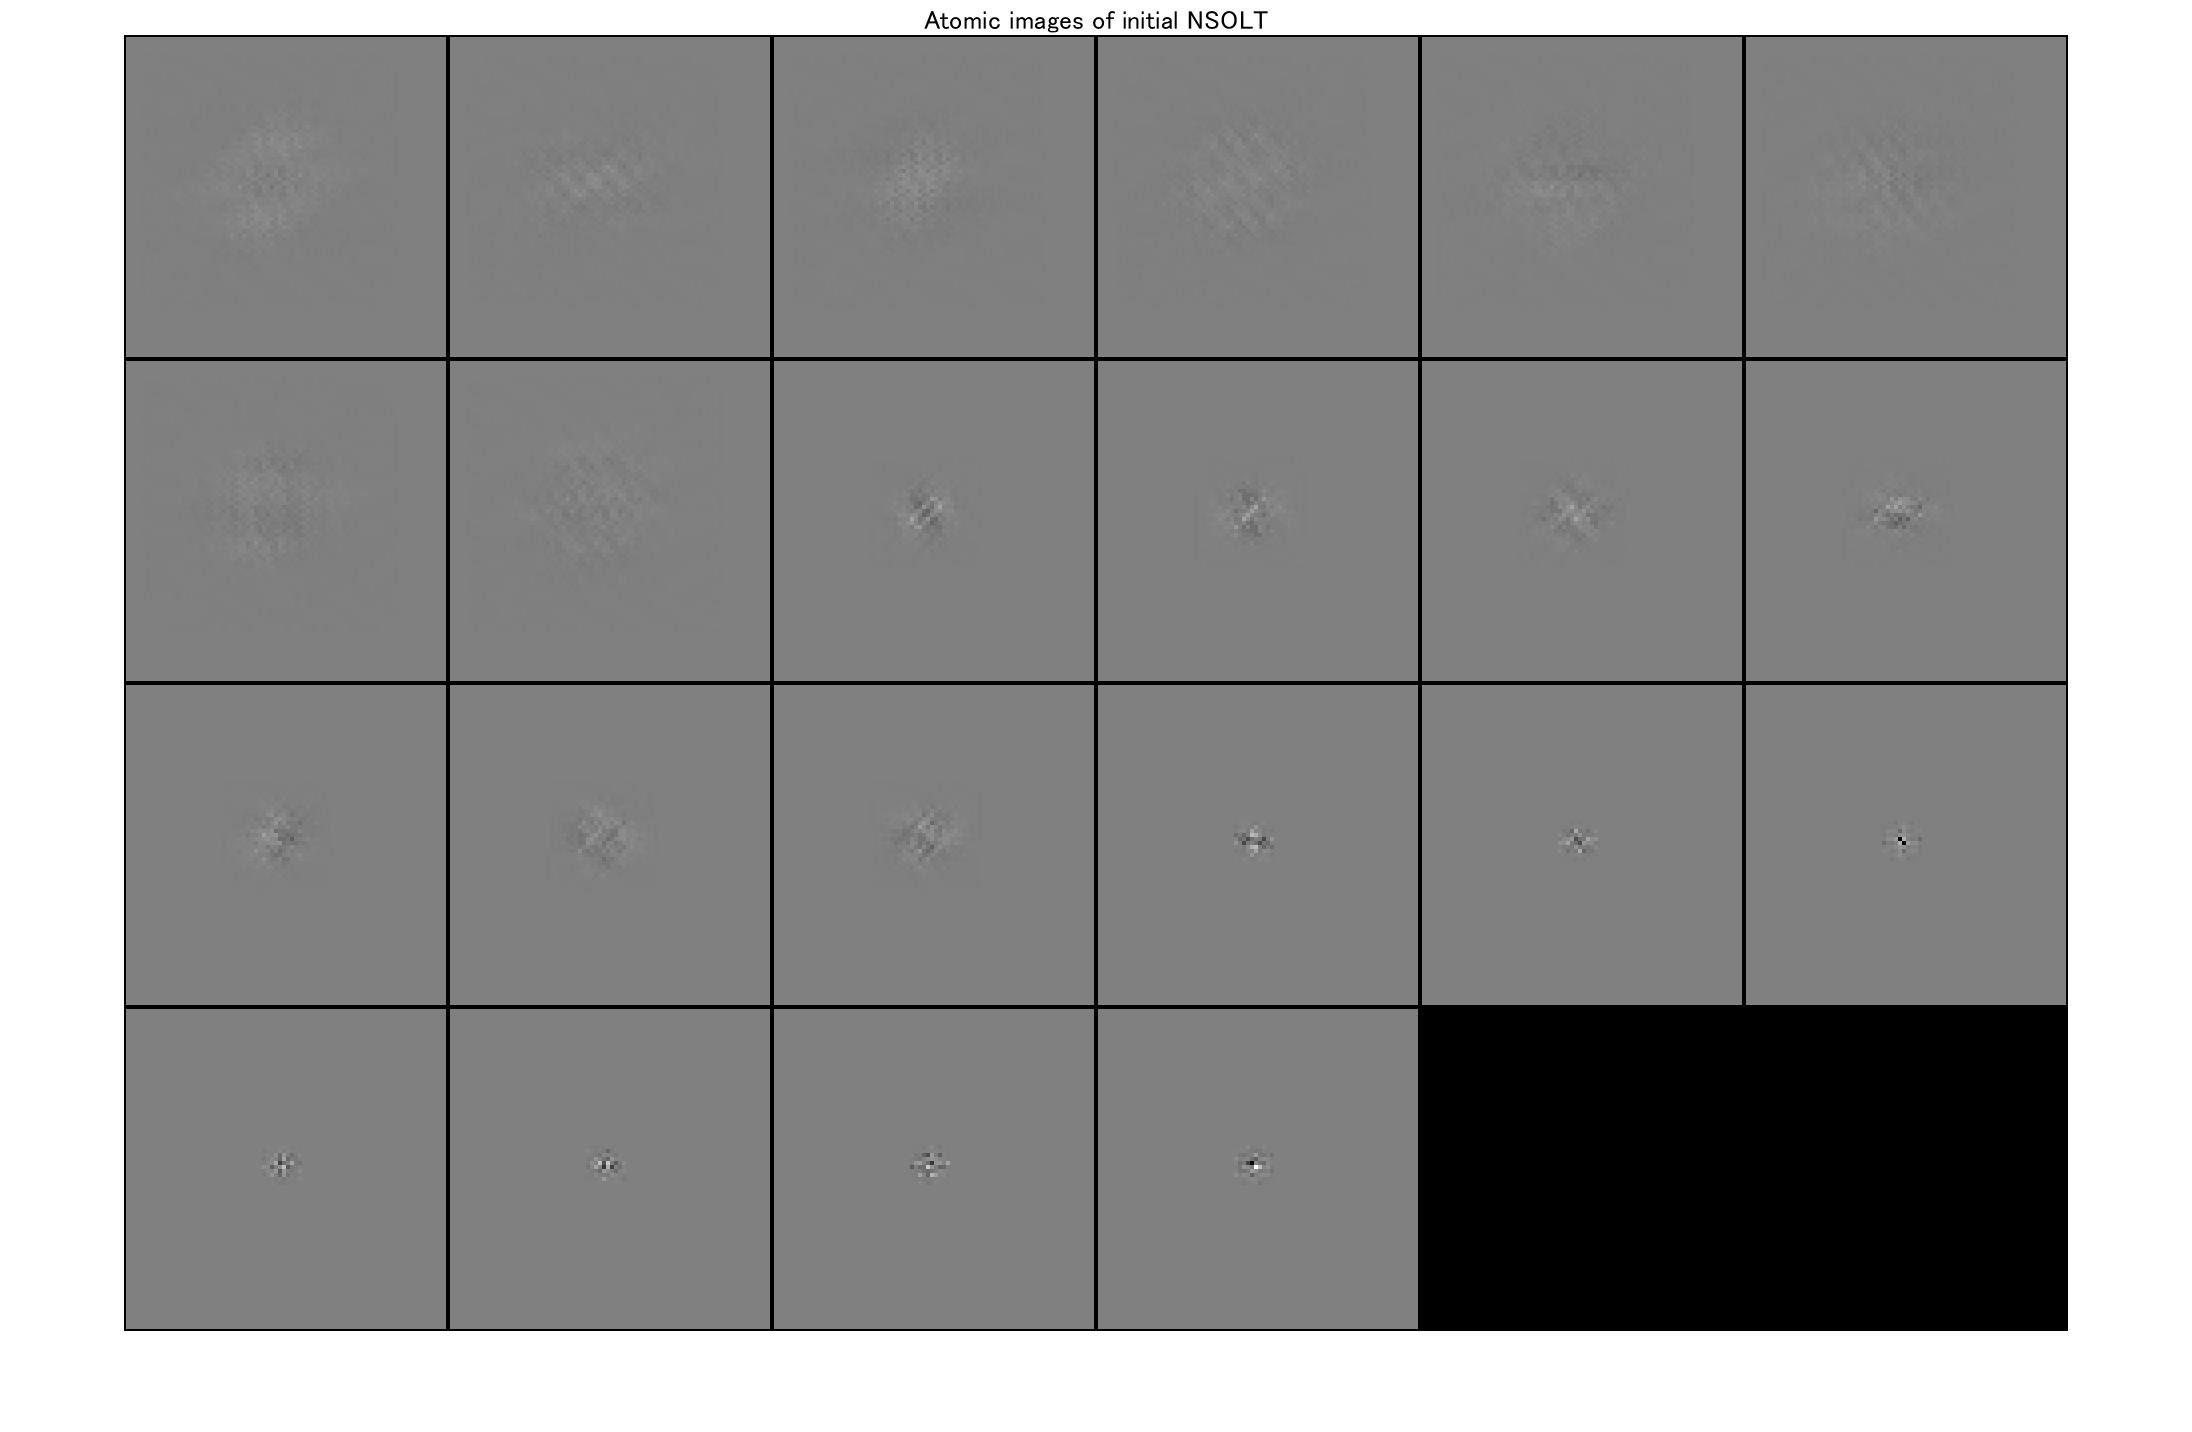

figure(4)
atomicimshow(synthesisnet)
title('Atomic images of initial NSOLT')

### Serialization of subband images

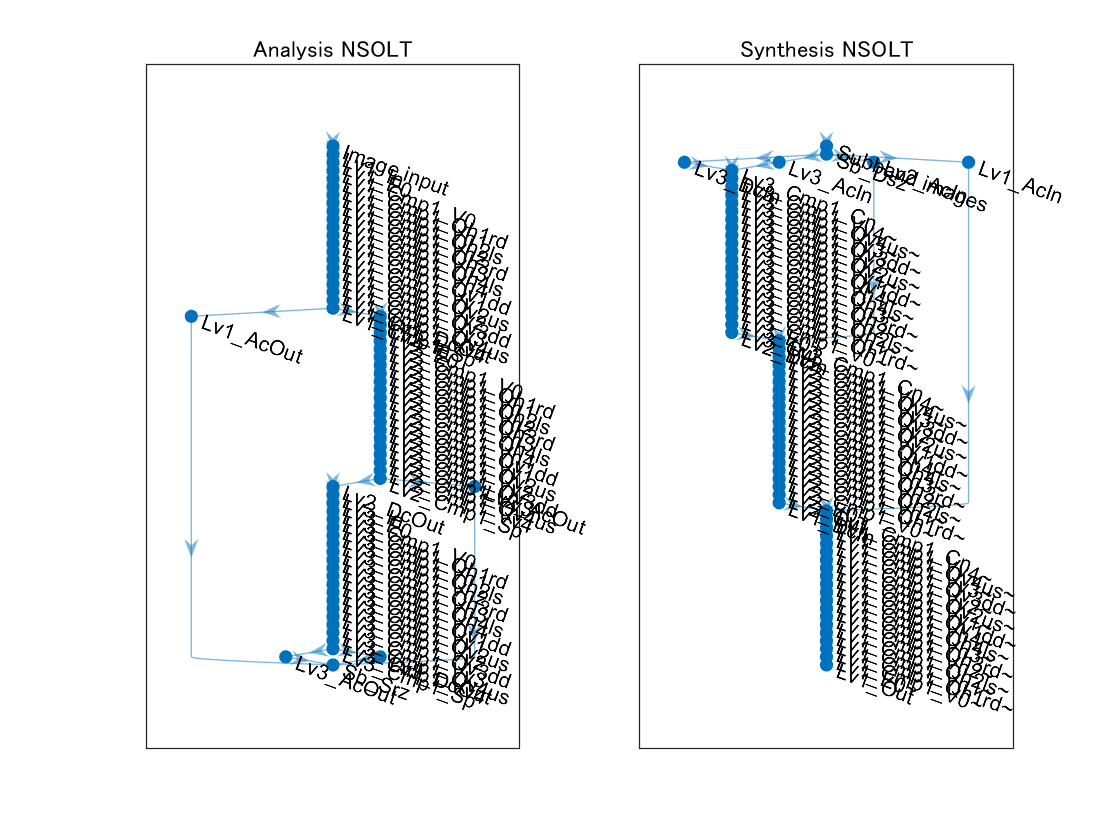

[analysislgraph_,synthesislgraph_] = fcn_attachserializationlayers(...
    analysislgraph,synthesislgraph,szPatchTrn);

figure(5)
subplot(1,2,1)
plot(analysislgraph_)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph_)
title('Synthesis NSOLT')

synthesisnet_ = dlnetwork(synthesislgraph_);

% Initialize
stdInitAng = pi/6;
nLearnables = height(synthesisnet_.Learnables);
for iLearnable = 1:nLearnables
    if synthesisnet_.Learnables.Parameter(iLearnable)=="Angles"
        synthesisnet_.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            synthesisnet_.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
synthesislgraph_ = layerGraph(synthesisnet_);
analysislgraph_ = fcn_cpparamssyn2ana(analysislgraph_,synthesislgraph_);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

analysisnet_ = dlnetwork(analysislgraph_);

### Confirmation of the adjoint relation (perfect reconstruction) w/ serialization

x = rand(szPatchTrn,'single');
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
dls = analysisnet_.predict(dlx);
dly = synthesisnet_.predict(dls);
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 9.1328e-12"



### Display the atomic images of serialized network

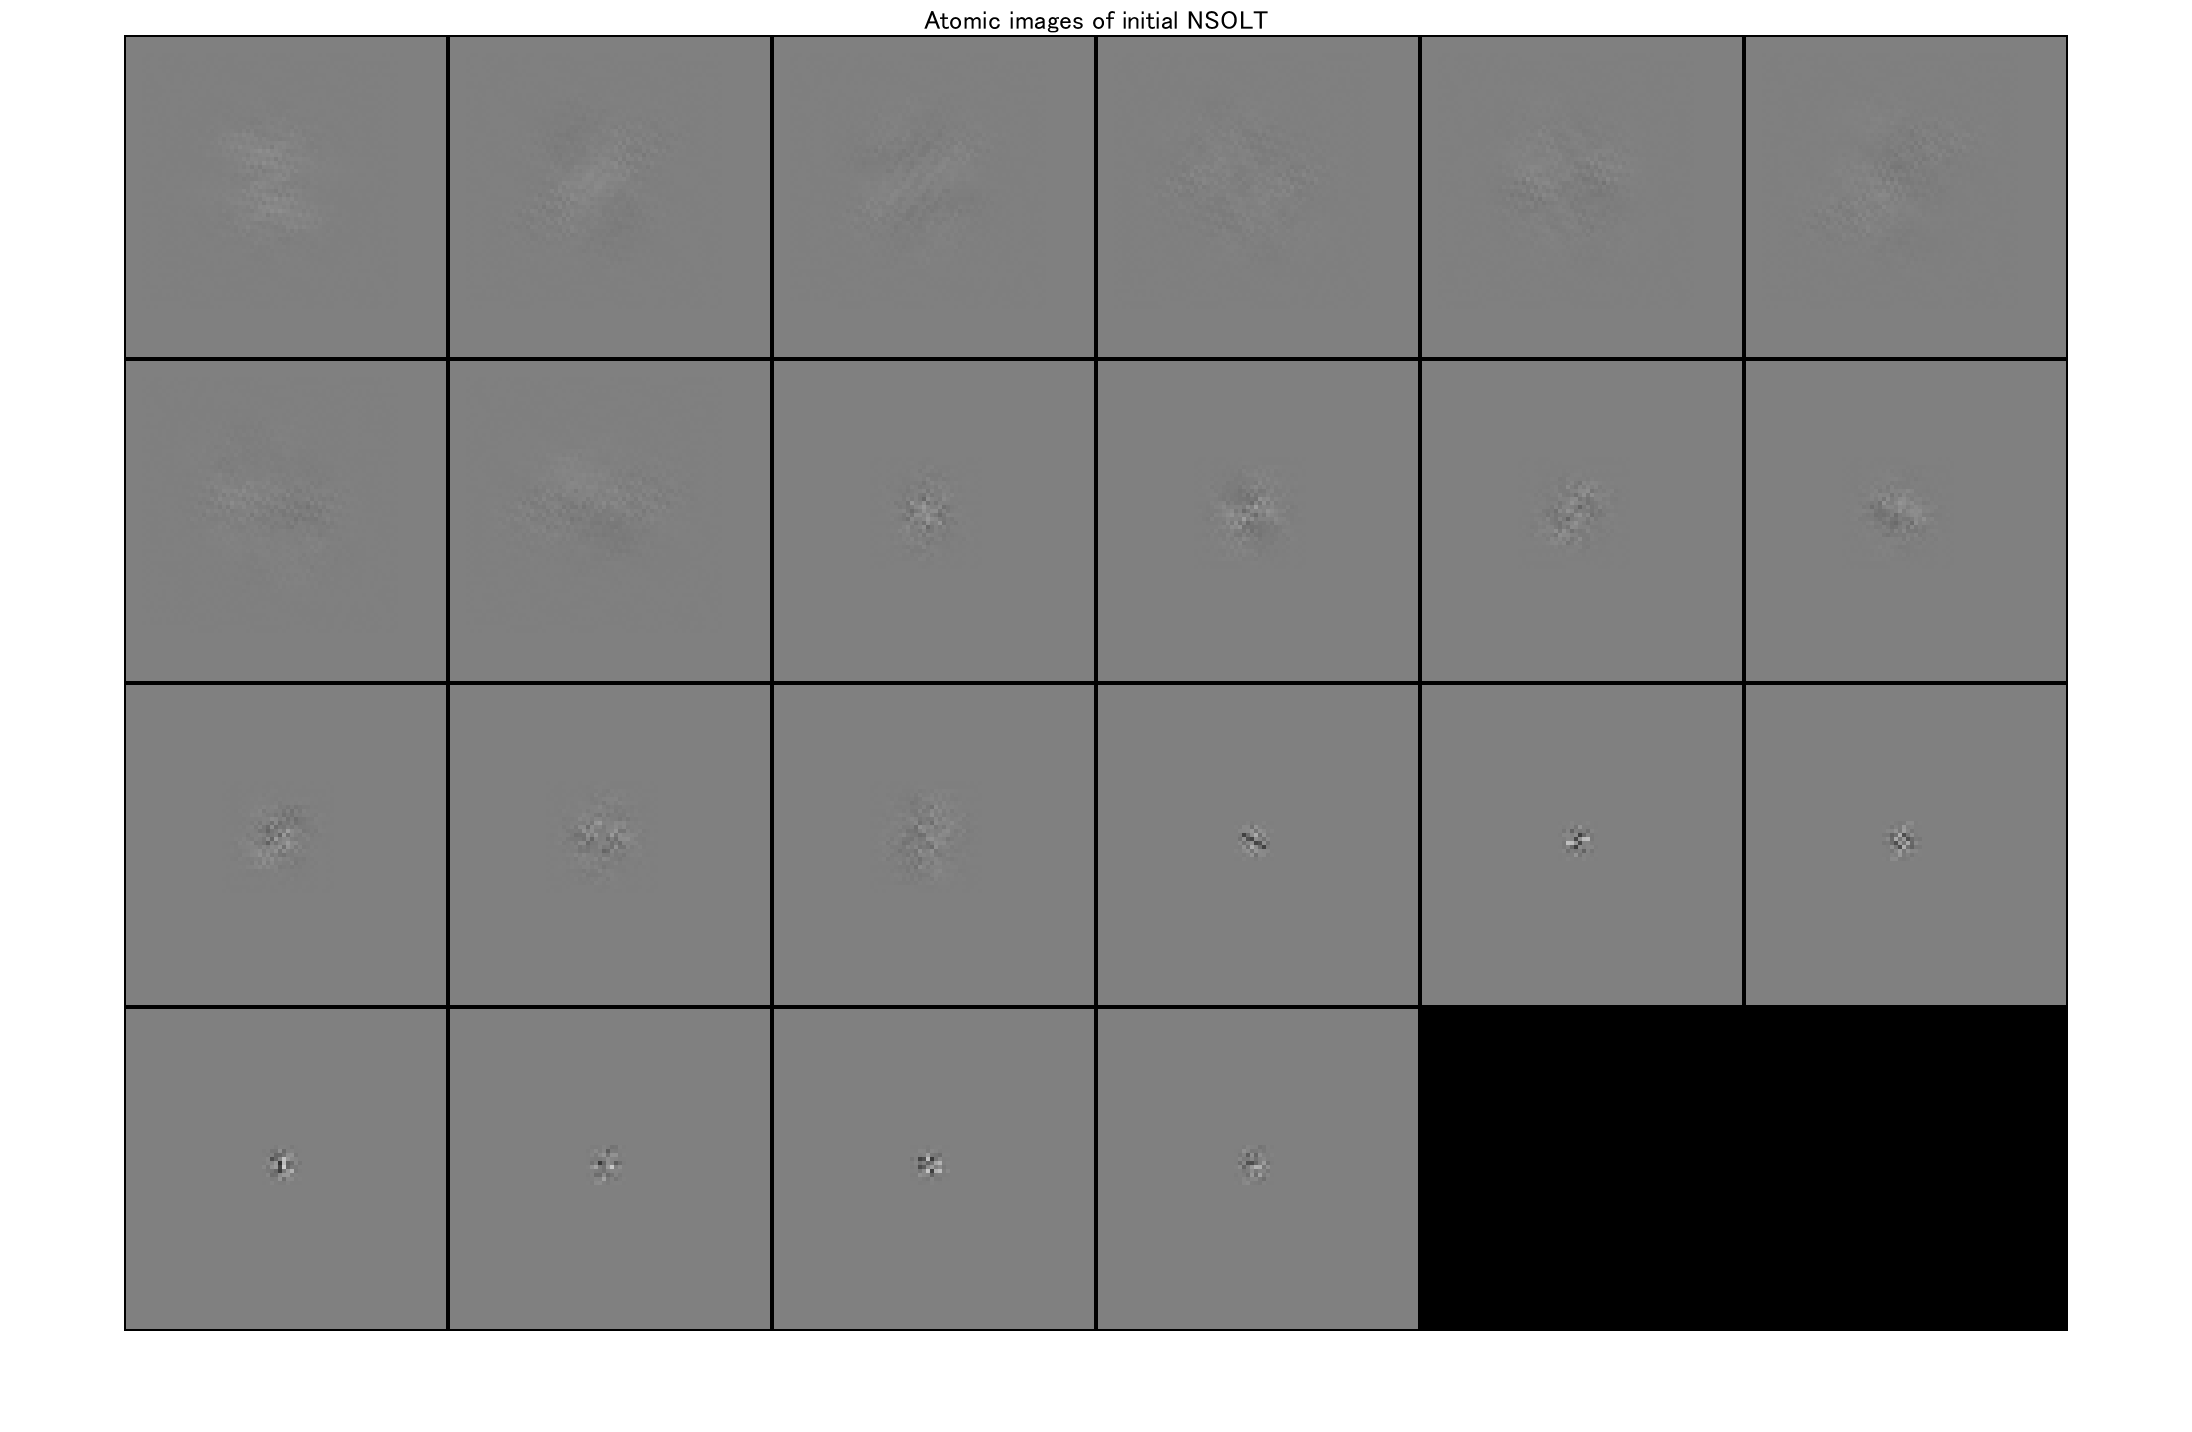

import saivdr.dcnn.*
figure(6)
atomicimshow(synthesisnet_)
title('Atomic images of initial NSOLT')

## Hierachical decomposition for 2-D RGB color image

% Decimation factor (Strides)
decFactor = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 4% [Ps Pa] (Ps=Pa)

nChannels =      4     4



% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4



% Number of tree levels
nLevels = 3;

% No DC-leakage
noDcLeakage = true;

% Number of components 
nComponents = 3; % RGB

## Construction of layers

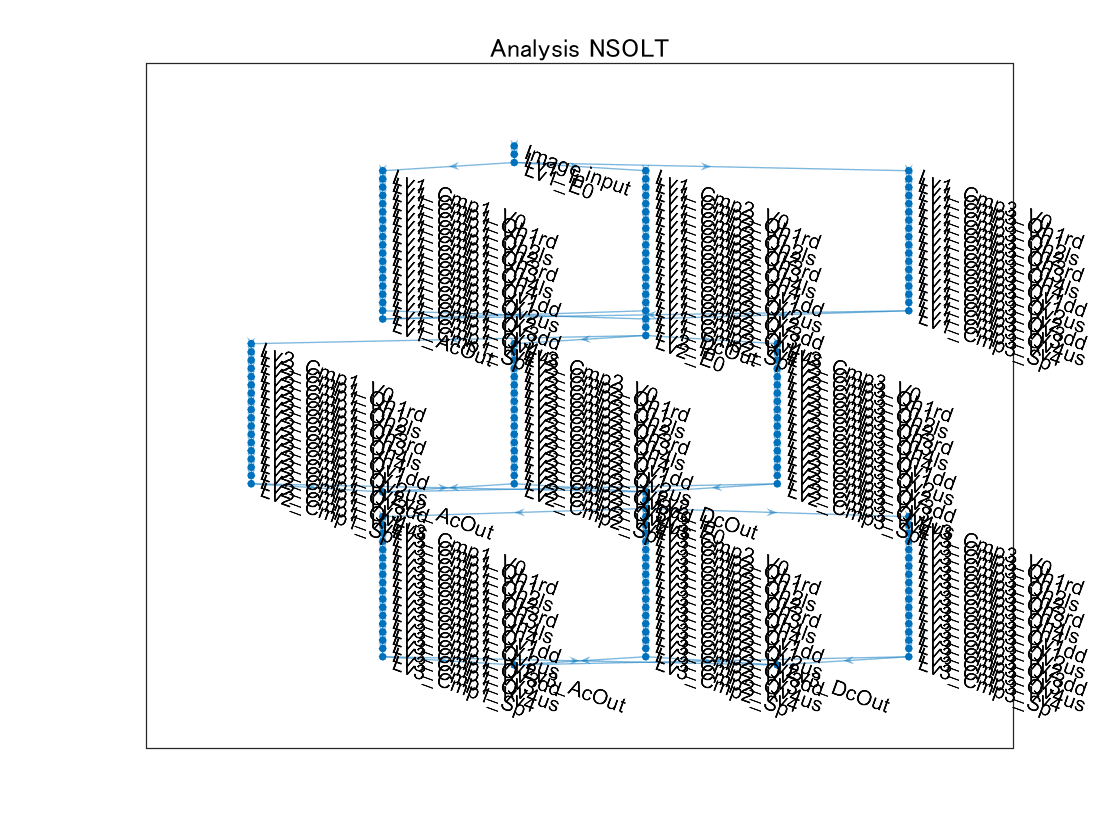

import saivdr.dcnn.*
analysislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Analyzer');
synthesislgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NUmberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Synthesizer');

figure(7)
plot(analysislgraph)
title('Analysis NSOLT')

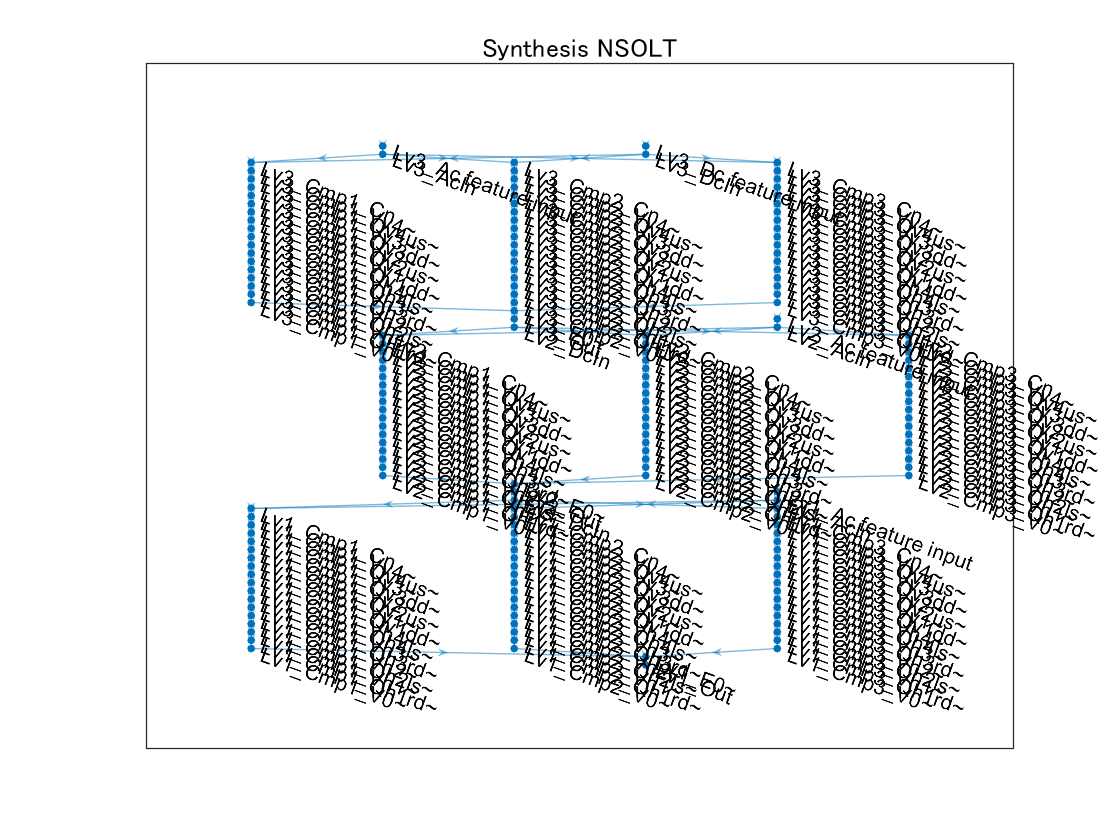

figure(8)
plot(synthesislgraph)
title('Synthesis NSOLT')


% Construction of synthesis deep learning network.
synthesisnet = dlnetwork(synthesislgraph);

% Initialize
stdInitAng = pi/6;
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
        synthesisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
synthesislgraph = layerGraph(synthesisnet);

% Construction of analysis deep learning network.
analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv1_Cmp2_V0~ to Lv1_Cmp2_V0
Copy angles from Lv1_Cmp2_Vh1~ to Lv1_Cmp2_Vh1
Copy angles from Lv1_Cmp2_Vh2~ to Lv1_Cmp2_Vh2
Copy angles from Lv1_Cmp2_Vh3~ to Lv1_Cmp2_Vh3
Copy angles from Lv1_Cmp2_Vh4~ to Lv1_Cmp2_Vh4
Copy angles from Lv1_Cmp2_Vv1~ to Lv1_Cmp2_Vv1
Copy angles from Lv1_Cmp2_Vv2~ to Lv1_Cmp2_Vv2
Copy angles from Lv1_Cmp2_Vv3~ to Lv1_Cmp2_Vv3
Copy angles from Lv1_Cmp2_Vv4~ to Lv1_Cmp2_Vv4
Copy angles from Lv1_Cmp3_V0~ to Lv1_Cmp3_V0
Copy angles from Lv1_Cmp3_Vh1~ to Lv1_Cmp3_Vh1
Copy angles from Lv1_Cmp3_Vh2~ to Lv1_Cmp3_Vh2
Copy angles from Lv

analysisnet = dlnetwork(analysislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

x = rand([szPatchTrn nComponents],'single');
clear dls
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
[dls{1:nLevels+1}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 2.9958e-11"



## Construction of whole layers

import saivdr.dcnn.*
nsoltlgraph = fcn_creatensoltlgraph2d(...
    'InputSize',szPatchTrn,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage, ...
    'Mode','Whole');
analyzeNetwork(nsoltlgraph)

© Copyright, Shogo MURAMATSU, All rights reserved.